**Essentials of Ultrasound Imaging: Lecture 2**

**GUI: Continuous Wave Reverberation Version 2**

**Author: Joseph Greene**

**Reference: Chapter 3.2, Diagnostic Ultrasound Imaging: Inside Out Ed.2**

Brief Description: In this Live Editor, we will explore how the Continuous Wave Reverb GUI Calulates reflected and transmitted power for a three layered media. Next, we will see how the GUI manipulates that data to derive a basic plot showing those results.

Inputs: z1 (impedence of layer 1), z2, z3, lambda (wavelength), d2 (thickness of layer 2)

Outputs: Zin (input impedence of layer 2 and 3), Rf (reflected power), Tf (tranmissted power), graph.


%%%%%%%%%%%%%
% User Inputs
%%%%%%%%%%%%%
%Impedences of the three layers (Should be MEGARayles)
z1=1*1e6;     % line impedance (Rayls) of 1st layer
z2=3*1e6;     % line impedance (Rayls) of 2nd layer
z3=9*1e6;     % load impedance (Rayls) of 3rd layer 
lambda = 1.9*10^-2; %Wavelength of 1.9 cm
d2 = lambda*0.5; %Thickness of layer 2 in wavelengths

%%%%%%%%%%%%%%%%%
%GUI Calculations
%%%%%%%%%%%%%%%%%

nt=258; %  number of points for plotting wave in layer 2 (DO NOT CHANGE)
% input variables
del=d2/(nt-1); %Stepsize for each point in layer 2
dd=del*(0:1:nt-1); %Array of second layer distance points
k2d= 2*pi*dd/lambda; %WaveVECTOR of layer 2
k1d= 2*pi*d2/lambda; %WaveNUMBER of layer 2
rf3=(z3-z2)/(z3+z2); %Reflectance Coefficient of second boundary

p2=exp(1i*k2d)+rf3.*exp(-1i*k2d); % pressure in layer
u2=exp(-1i*k1d)*((exp(1i*k2d)-rf3.*exp(-1i*k2d)))/z2; %particle  velocity in layer

% power transmitted into Z3 at second boundary
t2f3=2/((1+z1/z3)*cos(k1d)+1i*(z2/z3+z1/z2)*sin(k1d));

%First way to find reflection from both media
r = ((1-(z1/z3))*cos(k1d)+1i*((z2/z3-z1/z2)*sin(k1d)))...
    /((1+(z1/z3))*cos(k1d)+1i*((z2/z3+z1/z2)*sin(k1d)));

%Second way by first determining input impedence of second and third layers
zin = real(z2*(z3*cos(k1d)+1i*z2*sin(k1d))/(z2*cos(k1d)+1i*z3*sin(k1d))) %real b/c sin,cos produce very small imaginary values (10^-9)

zin = 9000000

rr = (zin-z1)/(z1+zin); %Check to see both yield same result (YAY!)

%Using randian sin instead of degree sin (sind) yields miniscule exponential terms (10^-19)
%That can create logit errors. I round to zero after the reflection gets negligable
if abs(r) < 0.001
    r = 0;
end

Rf = abs(rr)^2 %In practice, use input impedence way (simplier as stacks get more complex)

Rf = 0.6400


%Transmission out of the stacked media
Tf = 1-Rf

Tf = 0.3600

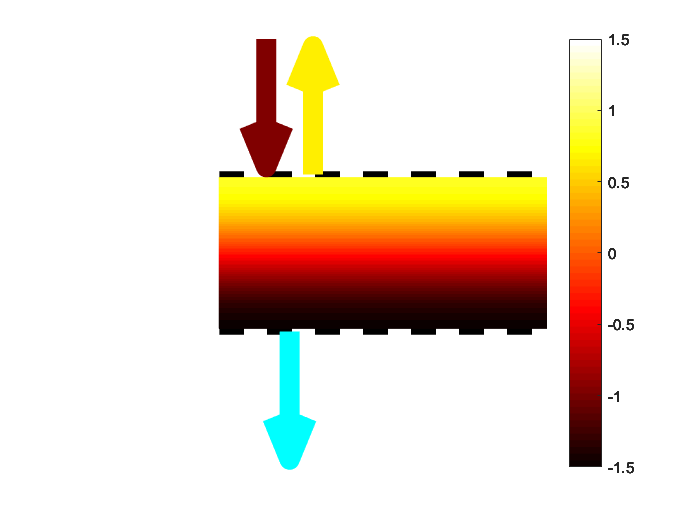



newp2 = real(p2); %To see wave nature, look just at real part of p2
newnewp2 = newp2-min(newp2(:));
obj.p2 = newp2;

%mapping values to hot map.
CMap = jet(64);
hotColor = hot;
coeff = [0 0]; % [slope intercept]

coeff(1) = 49/(3); %Normalized value to choose color to reflect both pos and neg values of p2. This function assumes values are positive so I relabel the colorbar as postiitve and negative in the appview
%coeff(1) = 49/(max(p2));
coeff(2) = 1;
val = round(coeff(1) * newnewp2 + coeff(2));

%Assign a color to each point along d2
for m = 1:256
    for n = 1:256
        colorMat(m,n,:) = hotColor(val(257-m),:);
    end
end

% refractions
%Convert reflection and transmission values into colors to plot arrows
rfColor = CMap(round(abs(Rf)*63+1),:);
tfColor = CMap(round(Tf*63+1),:);

%%%%%%%%%%%%%
%Draw Results
%%%%%%%%%%%%%

ImAxe = axes(); %Pair of blank axis to plot on
% Draw Lines on ImAxe
plot(ImAxe,1,1);
axis(ImAxe,'off');
axis(ImAxe,[-1 1 -1.5 1.5]);
line(ImAxe,[-.4 1], [0.55 0.55],'LineWidth',4,'Color','k','LineStyle','--'); %First boundary
line(ImAxe,[-.4 1], [-0.55 -0.55],'LineWidth',4,'Color','k','LineStyle','--');%Second boundary


hold(ImAxe,'on'); %Hold on to draw multiple things
%This line imposes an image onto the axes already defined. I.E
%This line is what draws the wave in layer 2!
image(ImAxe,'XData',linspace(-.4,1,256),'YData',linspace(-.53,.53,256),'CData',colorMat);

% Draw Arrows
%Input arrow
quiver(ImAxe, -0.2, 1.5, 0, -1, ...
    'Color',[0.5 0 0], ...
    'LineWidth',12, ...
    'MaxHeadSize',2);
%Reflection arrow
quiver(ImAxe, 0, .55, 0, 1, ...
    'Color',rfColor, ...
    'LineWidth',12, ...
    'MaxHeadSize',2); 
%Transmission Arrow
quiver(ImAxe, -0.1, -.55, 0, -1, ...
    'Color',tfColor, ...
    'LineWidth',12, ...
    'MaxHeadSize',2); 

% Draw ColorMaps in CMap Axes L/R
colormap(ImAxe,'hot');
h2 = colorbar(ImAxe);
h2.Limits = [-1.5 1.5];   

hold(ImAxe,'off') %Hold off to end graphing stage